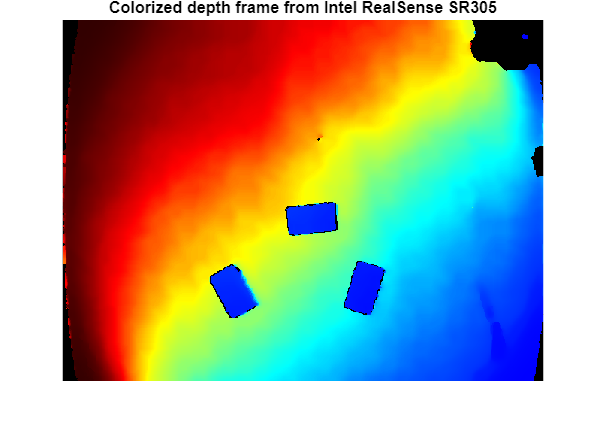

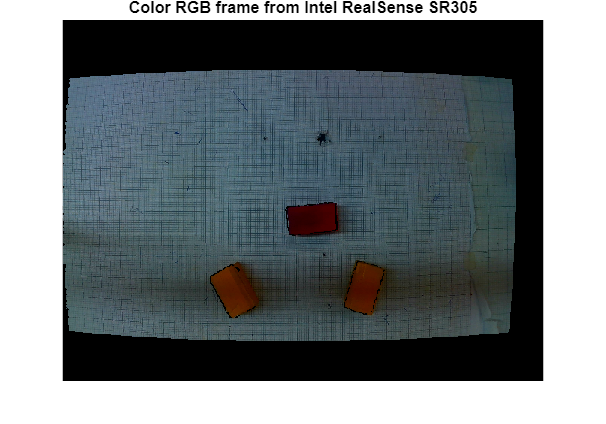

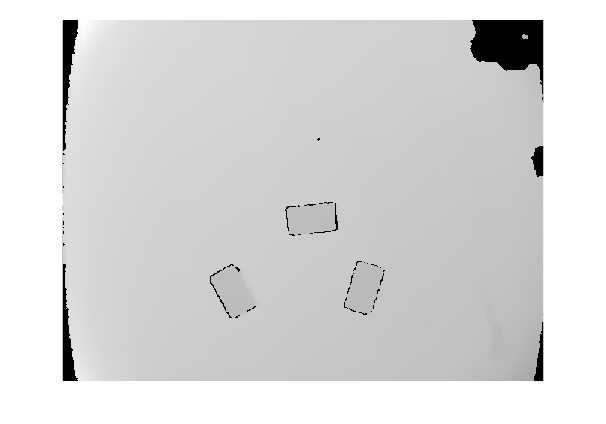

%% -------------------- 1. Initialization & Streaming --------------------
clc; clear; close all;

% Call your depth_example function
[imgDepth, imgRGB] = depth_example();


[rows, cols, ~] = size(imgRGB); 

% --- CHANGE 1: Explicit Depth/RGB Sync ---
% Ensure depth and RGB are exactly the same size for 1:1 pixel mapping
imgDepth = imresize(imgDepth, [rows, cols], 'nearest');
depthData = double(imgDepth);

%% -------------------- 2. Segment Red Block --------------------
imgLab = rgb2lab(imgRGB);
[L, a, b] = imsplit(imgLab);

R = double(imgRGB(:,:,1));
G = double(imgRGB(:,:,2));
B = double(imgRGB(:,:,3));

% Redness Ratio: Red should be significantly higher than Green and Blue
redMask = (R > 1.2*G) & (R > 1.2*B) & (R > 50);
redMask = imclose(redMask, strel('disk', 7)); % --- CHANGE 2: Slightly larger disk ---
redMask = bwareaopen(redMask, 800);           % --- CHANGE 3: Increased noise filter ---

%% -------------------- 3. Geometric Analysis (Body Frame) --------------------
% --- CHANGE 4: Added Major/Minor Axis Length for robust Bounding Box ---
stats = regionprops(redMask, 'Centroid', 'Orientation', 'MajorAxisLength', 'MinorAxisLength');

if isempty(stats)
    error('Red block not detected. Check lighting or thresholds.');
end

% We take the largest blob found
[~, idx] = max([stats.MajorAxisLength]);
s = stats(idx);

block_cx = s.Centroid(1);
block_cy = s.Centroid(2);
theta_deg = s.Orientation;
theta_rad = deg2rad(theta_deg);

% --- CHANGE 5: Mathematical Bounding Box Calculation ---
% This replaces the 'Extrema' logic which was causing the "bad outline"
L = s.MajorAxisLength / 2;
W = s.MinorAxisLength / 2;
% Rotation matrix for the box corners
R_box = [cosd(-theta_deg), -sind(-theta_deg); sind(-theta_deg), cosd(-theta_deg)];
corners = [-L, -W; L, -W; L, W; -L, W; -L, -W]; % Standard rectangle
rect = (R_box * corners')'; % Rotate
rect_x = rect(:,1) + block_cx; % Translate
rect_y = rect(:,2) + block_cy;

%% -------------------- 4. Depth (Z) & Translation --------------------
% --- CHANGE 6: Consistent Units (mm) ---
% depth_scaling in RealSense is typically 0.001 (1mm per unit)
% If your depth_example already applies scaling, verify the unit.
% We use a 5x5 median filter around the center for stability.
row_idx = round(block_cy);
col_idx = round(block_cx);
window = depthData(max(1,row_idx-2):min(rows,row_idx+2), max(1,col_idx-2):min(cols,col_idx+2));
Z = median(window(window > 0));

% If Z is in meters (0.5), convert to mm (500)
if Z < 10
    Z = Z * 1000; 
end

% Deprojection
fx = 475.27; fy = 475.27; % Using your provided focal lengths
cx_img = cols / 2; 
cy_img = rows / 2; 

X = (block_cx - cx_img) * Z / fx;
Y = (block_cy - cy_img) * Z / fy;

%% -------------------- 5. Transformation Matrix --------------------
% --- CHANGE 7: Orientation alignment ---
% 'Orientation' is relative to the X-axis. 
R_cb = [ cos(theta_rad),  sin(theta_rad), 0;
        -sin(theta_rad),  cos(theta_rad), 0;
         0,               0,              1];

T_cb = [R_cb, [X; Y; Z]; 
        0, 0, 0, 1];

fprintf('--- 4x4 Transformation Matrix (Camera to Block) ---\n');

--- 4x4 Transformation Matrix (Camera to Block) ---


disp(T_cb);

    0.2501    0.9682         0   64.1527
   -0.9682    0.2501         0   90.6125
         0         0    1.0000  366.3359
         0         0         0    1.0000



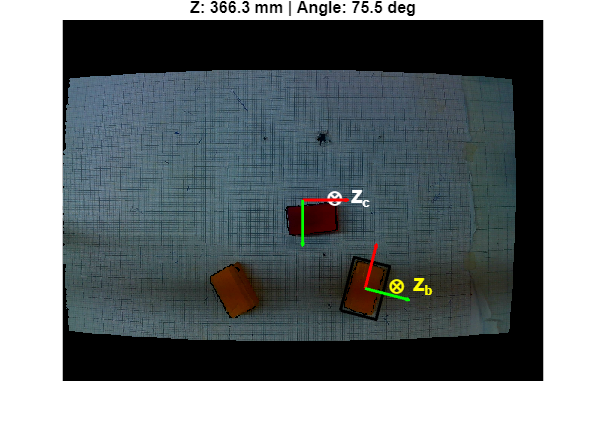


%% -------------------- 6. Final Visualization --------------------
figure('Name', 'Pose Estimation - Final Fix');
imshow(imgRGB); hold on;
axisLen = 60;

% --- CHANGE 8: Fixed Quiver Directions for Image Coordinates ---
% In images, +Y is DOWN. We adjust the green arrow to match visual reality.
plot(rect_x, rect_y, 'k', 'LineWidth', 2); % The new robust outline

% Block X-axis (Red)
quiver(block_cx, block_cy, axisLen*cos(-theta_rad), axisLen*sin(-theta_rad), 0, 'r', 'LineWidth', 2);
% Block Y-axis (Green)
quiver(block_cx, block_cy, axisLen*sin(theta_rad), axisLen*cos(theta_rad), 0, 'g', 'LineWidth', 2);

% Labels
text(block_cx, block_cy, '  \otimes Z_b', 'Color', 'y', 'FontSize', 12, 'FontWeight', 'bold');
text(cx_img, cy_img, '  \otimes Z_c', 'Color', 'w', 'FontSize', 12, 'FontWeight', 'bold');

% Camera World Frame
quiver(cx_img, cy_img, axisLen, 0, 0, 'r', 'LineWidth', 2); 
quiver(cx_img, cy_img, 0, axisLen, 0, 'g', 'LineWidth', 2); 

title(sprintf('Z: %.1f mm | Angle: %.1f deg', Z, theta_deg));
hold off;